close all 
%FEEDBACK CONTROLS PROJECT 
%Adam Chung 
%12/02/2020

%INIT
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
robot = loadrobot("kinovaJacoJ2N6S200","Gravity",[0 0 -9.81]); %Create rigidBodyTree obj
iviz = interactiveRigidBodyTree(robot,"MarkerBodyName","j2n6s200_end_effector"); %Sim enviroment
ax = gca;
plane = collisionBox(0,0,0.025); %Floor init
plane.Pose = trvec2tform([0.25 0 -0.055]); %Floor pose
show(plane,'Parent', ax);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Define and plot Trajectory 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%trajectory = 1 ==> Pentagon 
%trajectory = 2 ==> Sine wave
%trajectory = 3 ==> Random 

trajectory = 1; 
switch trajectory
    case 1
        t = (0:2:10)'; % Time
        count = length(t);
        center = [0 0 1];
        radius = 0.4;
        theta = t*(2*pi/t(end));
        points = center + radius*[cos(theta) sin(theta) zeros(size(theta))];
        hold on
        plot3(points(:,1),points(:,2),points(:,3),'or','LineWidth',2,'Parent',ax)
        hold off
    case 2
        t = (-1:0.01:1)'; 
        count = length(t);
        theta = t*(2*pi/t(end));
        x = t; 
        y = 0.4*sin(t*16); 
        z = ones(size(y)); 
        points = [x y z];
        hold on
        plot3(points(:,1),points(:,2),points(:,3),'--r','LineWidth',2,'Parent',ax)
        hold off
    case 3 
        numPoints = 4; 
        count = numPoints; 
        x = (-1 + (1+1)*rand(numPoints,1,'double'))/1.5
        y = (-1 + (1+1)*rand(numPoints,1,'double'))/1.5
        z = 0.25 +rand(numPoints,1,'double')/1.5
        points = [x y z]; 
        hold on
        plot3(points(:,1),points(:,2),points(:,3),'or','LineWidth',2,'Parent',ax)
        hold off
end

x =     0.5915
   -0.0974
   -0.6225
    0.5726


y =     0.5666
   -0.1889
   -0.3200
    0.3825


z =     0.5911
    0.6250
    0.7065
    0.3116


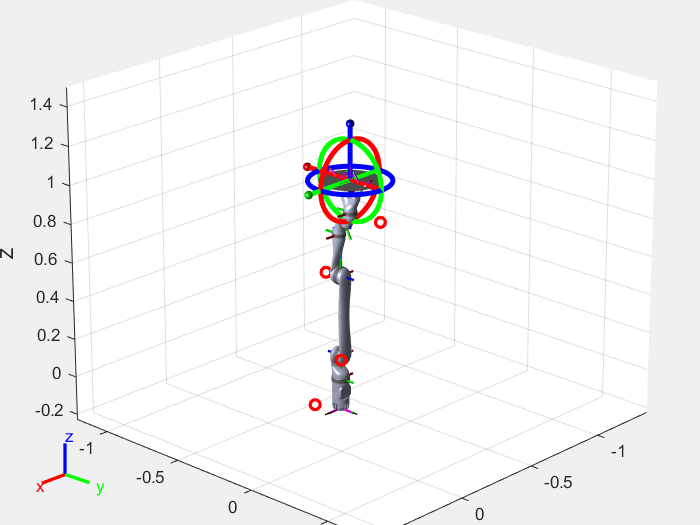

MATLAB System block 'PD/PD Controller/Gravity Torque/MATLAB System' error occurred when invoking 'stepImpl' method of 'robotics.slmanip.internal.block.GravityTorqueBlock'.

Caused by:
    Error using simulate (line 92)
    Program interruption (Ctrl-C) has been detected.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Solve IK to obtain desired joint pos time series 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q0 = homeConfiguration(robot); 
ndof = length(q0);
qs = zeros(ndof, count); %preallocate solution series 

ik = inverseKinematics('RigidBodyTree', robot); %init ik obj
weights = [0.2, 0.2, 0.2, 1, 1, 1]; %weights for xyz-rot and xyz
endEffector = 'j2n6s200_end_effector';

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
 % Solve for the configuration satisfying the desired end effector
 % position
 point = points(i,:);
 [qSol,qSolInfo] = ik(endEffector,trvec2tform(point),weights,qInitial);
 
 %place soln in array of size 8x1 
 q_t_Sol = [qSol(1).JointPosition;qSol(2).JointPosition;qSol(3).JointPosition;qSol(4).JointPosition;...
            qSol(5).JointPosition;qSol(6).JointPosition;qSol(7).JointPosition;qSol(8).JointPosition];
 % Store the configuration
 qs(:,i) = q_t_Sol;
 % Start from prior solution
 qInitial = qSol;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




%Simulate desired trajectories with controllers and choose which one to show
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
simout_CTC = sim('CTC.slx');
simout_PD = sim('PD.slx'); 


%controller = 1 ==> Computed Torque Control
%controller = 2 ==> PD Control 

controller = 1; 
switch controller 
    case 1 
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_CTC.tout)/(max(simout_CTC.tout)));
        for i = 1:length(simout_CTC.tout)
            iviz.Configuration = simout_CTC.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end
        q = simout_CTC.q_ctc; 
        q_desired = simout_CTC.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
    case 2
        % Visualize the motion using the interactiveRigidBodyTree
        iviz.ShowMarker = false;
        iviz.showFigure;
        rateCtrlObj = rateControl(length(simout_PD.tout)/(max(simout_PD.tout)));
        for i = 1:length(simout_PD.tout)
            iviz.Configuration = simout_PD.yout{1}.Values.Data(i,:);
            waitfor(rateCtrlObj);
        end  
        q = simout_PD.q_pd; 
        q_desired = simout_PD.q_desired; 
        figure(3)
        hold on 
        plot(q)
        plot(q_desired,'--r')
        hold off
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%